# **Matlab案例代码解析**

## 4. 图像信号处理案例

### 4.1 滤波

#### 4.1.4 小波滤波

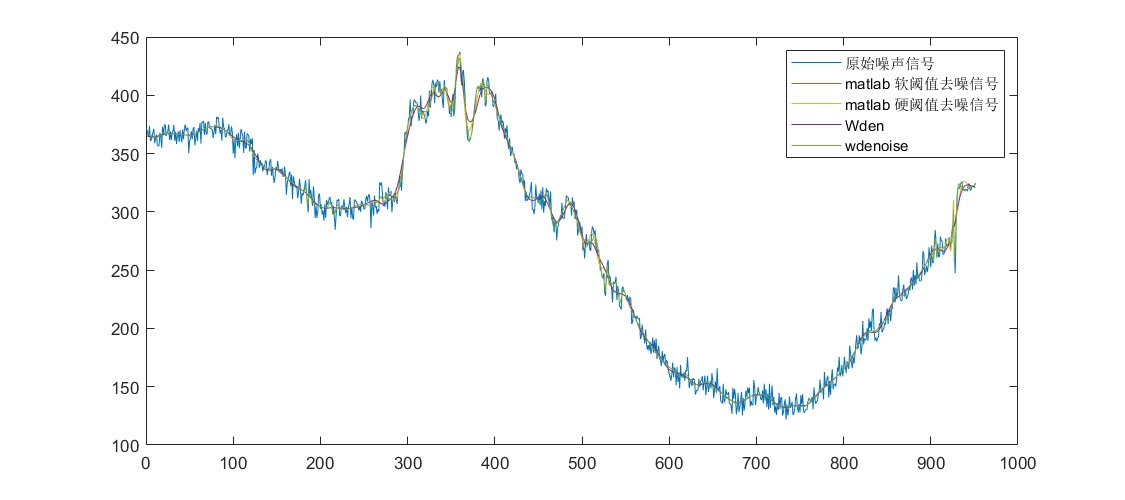

clear;clc;   
load leleccum;  
indx = 2500:3450;  
noisez = leleccum(indx);   
wname = 'sym8';   
lev = 4;  
% 小波分解
[c, l] = wavedec(noisez, lev, wname);
[Lo_D, Hi_D, Lo_R, Hi_R] = wfilters(wname);  
% threshold value 
sigma = wnoisest(c, l, 1);  % 使用库函数 wnoisest 提取第一层的细节系数来估算噪声的标准偏差  
N = numel(noisez);          % 整个信号的长度 
thr = sigma*sqrt(2*log(N)); % 最终阈值  
% 全局阈值处理  
keepapp = 1; % 近似系数不作处理  
denoisexs = wdencmp('gbl', c, l, wname, lev, thr, 's', keepapp);  
denoisexh = wdencmp('gbl', c, l, wname, lev, thr, 'h', keepapp);  
sigOut1 = Wden(noisez, N);
sigOut2 = wdenoise(noisez, 4)';
% 作图  
figure('Position', [10, 10, 900, 400]);
plot(noisez) 
hold on
plot(denoisexs) 
plot(denoisexh)
plot(sigOut1)
plot(sigOut2)
hold off
legend('原始噪声信号', 'matlab 软阈值去噪信号', 'matlab 硬阈值去噪信号', 'Wden', 'wdenoise');